% Clean up
clear all; close all; clc;


% read data
data = csvread('all.csv');
time = data(:,1);
asym_def = data(:, 2);
yaw_ref = data(:, 3);
yaw = data(:, 4);
x = data(:, 5);
y = data(:, 6);
z = data(:, 7);

% time calc on assumptions of code running at 100Hz
freq = 100;
end_time = length(x) / freq;
%time = linspace(0,end_time, length(x))';

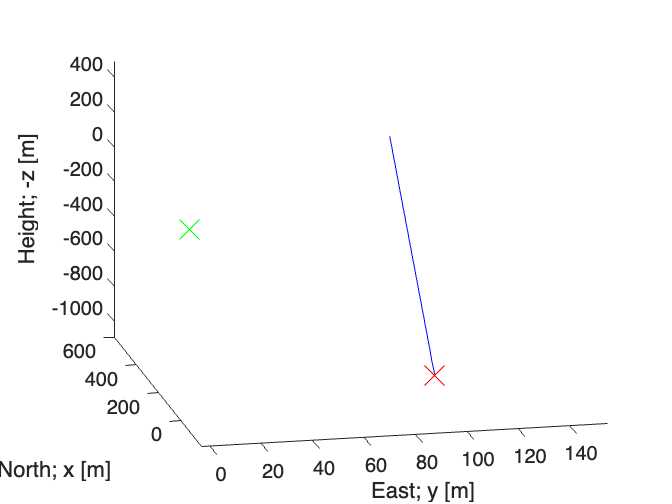

% 3D trajectory
figure(1)
plot3(y, x, -z, 'blue')
hold on
% start point
scatter3(y(1), x(1), -z(1), 200, 'red', 'x')
% target point
scatter3(0,0,0, 200, 'green', 'x')
hold off

xlabel('East; y [m]')
ylabel('North; x [m]')
zlabel('Height; -z [m]')

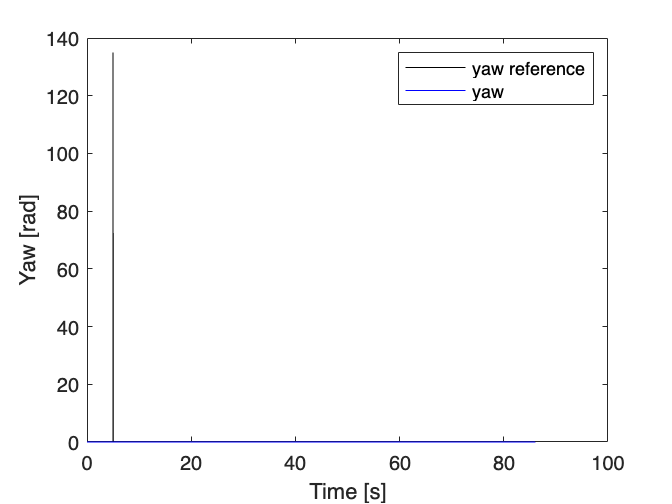

% yaw vs. yaw_ref
figure(2)
plot(time, yaw_ref, 'k')
hold on
plot(time, yaw, 'b')
hold off

xlabel('Time [s]')
ylabel('Yaw [rad]')
legend('yaw reference', 'yaw')

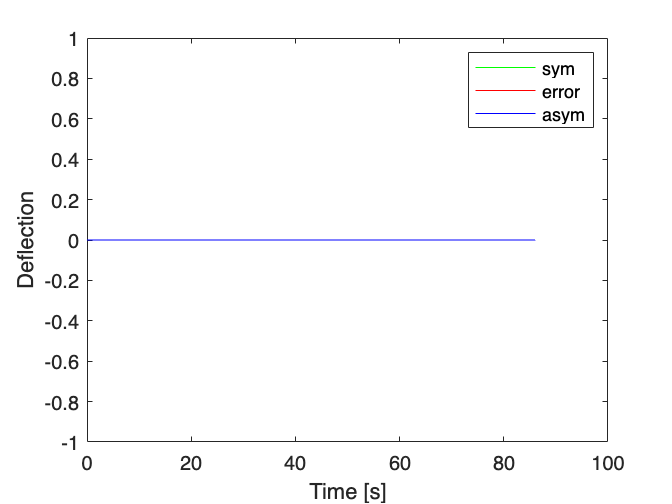

% inputs
figure(3)
plot(time, linspace(0,0,length(x)), 'g')
hold on
plot(time, yaw_ref - yaw, 'r')
plot(time, asym_def, 'b')
hold off

xlabel('Time [s]')
ylabel('Deflection')
legend('sym','error','asym')